%Export ground truth from image labeler (gTruth.mat is output)

load gTruth.mat

% create pixel label datastore

pxds = pixelLabelDatastore(gTruth);

%create pixel label image datastore for training

pximds = pixelLabelImageDatastore(imds,pxds);  %%%needs to be same number of files

%set training options

options = trainingOptions('sgdm','InitialLearnRate',1e-3, ...
    'MaxEpochs',20,'VerboseFrequency',10);

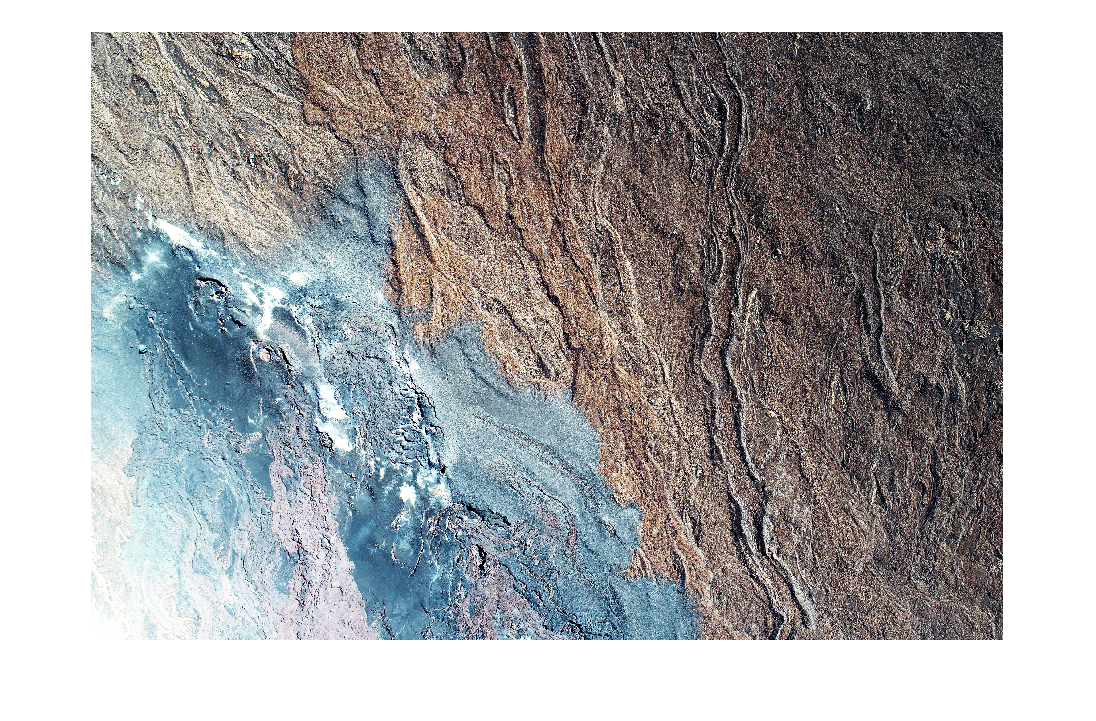

% Displaying a single raw image without overlay

I = readimage(imds,1);
I = histeq(I);
imshow(I)

% Set label classes

classes = galLabels{1:6,"Name"};

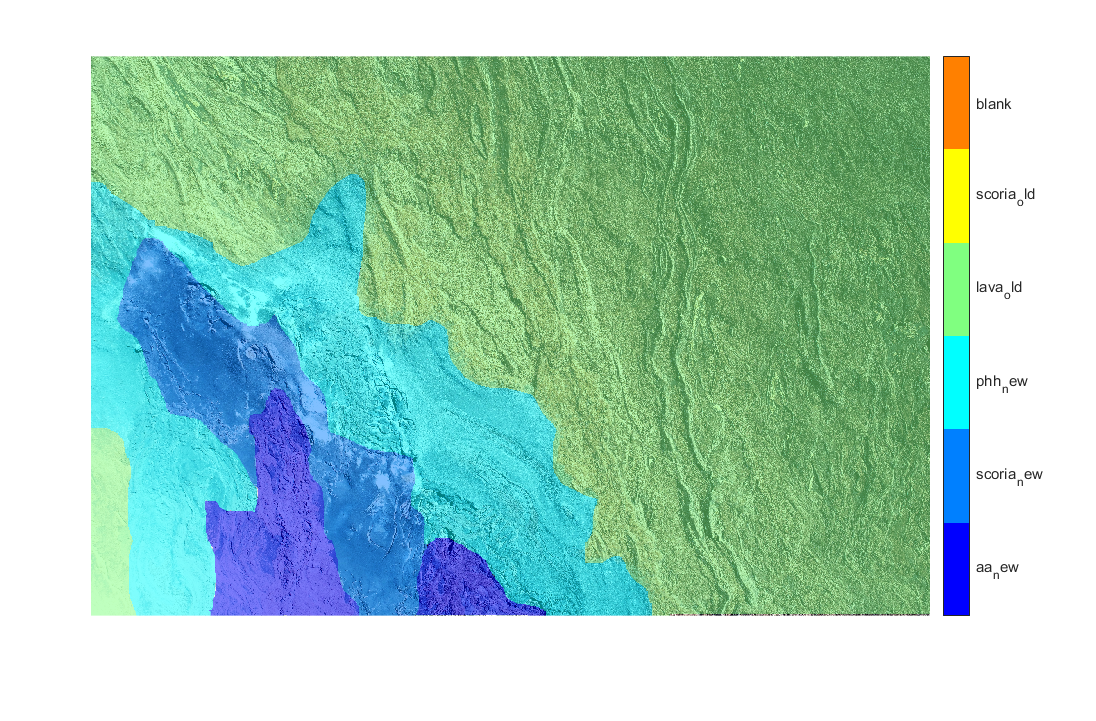

%Display training image with pixel label overlay

cmap = jet; %set colormap

C = readimage(pxds,1);
B = labeloverlay(I,C,'ColorMap',cmap);
imshow(B)
pixelLabelColorbar(cmap,classes); %display color bar


%can I rename the labels for display? 

%for i = 1:numel(imds)
%    
%    temp = readimage(pxds,i);
%    temp2 = histeq(temp);
%    imshow(temp2)
%    
% end

Error using histeq
Expected input number 1, I, to be one of these types:

uint8, uint16, double, int16, single

Instead its type was categorical.

Error in histeq (line 106)
    validateattributes(a,{'uint8','uint16','double','int16','single'}, ...